# Problem -1}

% Filter 
Fs = 720;
Ap = -1;
Fe = 10;
Ast = 40;
Fse = 20;

% Butterworth filter
[n, wn] = buttord(Fe/(Fs/2), Fse/(Fs/2), Ap, Ast);
[b,a] = butter(n, wn);

% Transfer function
Y = tf(b, a);

% Plotting Pole-Zero Map
figure;
pzmap(Y);

% Plotting Bode
bode(Y);

% Impulse response
t = 0:1/Fs:1;
x = [1, zeros(1, length(t)-1)];
y = filter(b, a, x);

figure;
subplot(2, 1, 1);
plot(t, y);
title('Impulse');

% Step response
u = ones(size(t));
y_step = filter(b, a, u);

subplot(2, 1, 2);
plot(t, y_step);
title('Step');
grid on;
xlabel('Time (s)');



# Problem -2}

data = importdata('ECG_Data.txt');
filtered_data = filter(b, a, data);
t = (0:(length(data) - 1)) / Fs;

% Plotting
figure;
% Original
plot(t, data, 'b', 'LineWidth', 1.5);
hold on;
% Filtered
plot(t, filtered_data, 'r', 'LineWidth', 1.5);
title('Original vs. Filtered');
xlabel('Time(s)');
ylabel('Amplitude');
legend('Original ECG', 'Filtered ECG');


# Problem -3}

figure;
spectrogram(y, hamming(512), 256, 512, Fs, 'yaxis');
title('Spectrogram of Original Audio');

% Design a Butterworth band-pass filter
order = 10; % Filter order
Fc1 = 500; % Lower cutoff frequency in Hz
Fc2 = 3000; % Upper cutoff frequency in Hz

% Normalize cutoff frequencies[y, Fs] = audioread('C:\Users\Student\Documents\Amar\EXP-6\instru3.wav');

Wn1 = Fc1 / (Fs/2);
Wn2 = Fc2 / (Fs/2);

% Design the filter
[b, a] = butter(order, [Wn1, Wn2], 'bandpass');

% Apply the filter to the audio signal
filtered_signal = filter(b, a, y);

% Write the filtered signal to a new WAV file
audiowrite('filtered_audio.wav', filtered_signal, Fs);

% Plot the spectrogram of the filtered signal
figure;
spectrogram(filtered_signal, hamming(512), 256, 512, Fs, 'yaxis');
title('Spectrogram of Filtered Audio (Fundamental Frequency)');






# Problem -4}

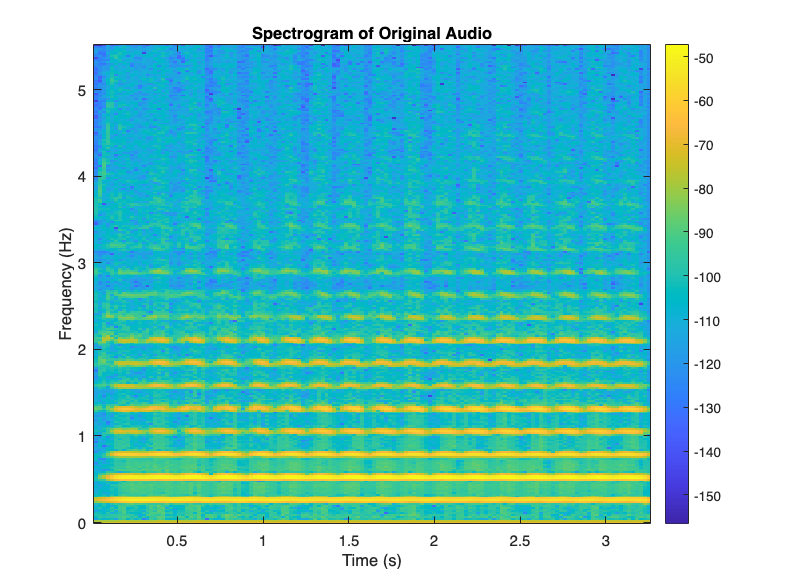

Error using pwelch
Expected x to be finite.

Error in signal.internal.spectral.welchparse>parse_inputs (line 111)
validateattributes(x2,{'single','double'}, {'finite','nonnan'},'pwelch','x')

Error in signal.internal.spectral.welchparse (<a href="matl

% Filter 
Fs = 720;

Ap = 1; 
Fe = 10;
Ast = 40; 
Fse = 20; 

% Butterworth filter 
[n_butter, wn_butter] = buttord(Fe/(Fs/2), Fse/(Fs/2), Ap, Ast);
[b_butter, a_butter] = butter(n_butter, wn_butter);

% Type I Chebyshev filter 
[n_cheby, wn_cheby] = cheb1ord(Fe/(Fs/2), Fse/(Fs/2), Ap, Ast);
[b_cheby, a_cheby] = cheby1(n_cheby, Ap, wn_cheby);

% Bode plot
freq_range = 0:0.01:Fs/2;
H_butter = freqz(b_butter, a_butter, freq_range, Fs);
H_cheby = freqz(b_cheby, a_cheby, freq_range, Fs);

figure;
semilogx(freq_range, 20*log10(abs(H_butter)), 'b', 'LineWidth', 2);
hold on;
semilogx(freq_range, 20*log10(abs(H_cheby)), 'r', 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Bode Plot Comparison: Butterworth vs. Chebyshev');
legend('Butterworth', 'Chebyshev');
grid on;

% Impulse response 
t = 0:1/Fs:1;
x = [1, zeros(1, length(t)-1)];

y_butter = filter(b_butter, a_butter, x);
y_cheby = filter(b_cheby, a_cheby, x);

figure;
subplot(2, 1, 1);
stem(t, y_butter, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Impulse Response Comparison: Butterworth');
grid on;

subplot(2, 1, 2);
stem(t, y_cheby, 'r', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Impulse Response Comparison: Chebyshev');
grid on;

% Step response
step_butter = cumsum(y_butter);
step_cheby = cumsum(y_cheby);

figure;
subplot(2, 1, 1);
plot(t, step_butter, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Step Response Comparison: Butterworth');
grid on;

subplot(2, 1, 2);
plot(t, step_cheby, 'r', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Step Response Comparison: Chebyshev');
grid on;
